# Hopper dynamics. Euler's angles Plant. 17.04.2025

#### Mass Consumption and Inertia, center of mass interpolation introduced

#### MPC and LQR for robustness (LQR compensation for disturbamce)

### In Progress

clc; clear all; close all;

SimulinkOpen = false;
disturbOn = false;
GravityCompansation = true;
Euler_Angles = true;
RollUp = false;
DiagInertia = true;

## Generate trajectory (Earth Frame)

run("Generate_trajectory.m")

Tjet = 45;
Troll = 3;
Tpy = 3;
e_x = 0;
e_y = 0;
e_z = 0;
l_2 = 0.3608544;    % 0.403;
l_3 = 0.3608544;    % 0.403;
l_4 = 0.3608544;    % 0.403;
l_5 = 0.3608544;    % 0.403;
l_6 = 0.2717;       % 0.263
l_7 = 0.2717;       % 0.263
l_8 = 0.2717;       % 0.263
l_9 = 0.2717;       % 0.263
d_2 = 0.305;    % 0.039;
d_3 = 0.305;    % 0.039;
d_4 = 0.305;    % 0.039;
d_5 = 0.305;    % 0.039;
d_6 = 0.2739;   %-0.018;
d_7 = 0.2739;
d_8 = 0.2739;
d_9 = 0.2739;
action_params = [
%     Thrust  ex ey   ez    Froll Fpitch Fyaw Lphi Lpitch Lyaw
     Tjet,  e_x, e_y, e_z,    0,  0,   0,   0,  0,  0;
     Troll, l_2, d_2,   0,  -45,  90,  0,   45, 90, 0;
     Troll, l_3, d_3,   0,   45,  90,  0,  -45, 90, 0;
     Troll, l_4, d_4,   0,  135,  90,  0, -135, 90, 0;
     Troll, l_5, d_5,   0, -135,  90,  0,  135, 90, 0;
     Tpy,   l_6, d_6,   0,    0,  0,   0,   90, 90, 0;
     Tpy,   l_7, d_7,   0,    0,  0,   0,    0, 90, 0;
     Tpy,   l_8, d_8,   0,    0,  0,   0,  -90, 90, 0;
     Tpy,   l_9, d_9,   0,    0,  0,   0,  180, 90, 0
];
clear e_y e_z l_2 l_3 l_4 l_5 l_6 l_7 l_8 l_9 d_2 d_3 d_4 d_5 d_6 d_7 d_8 d_9;
geometry = action_params(:, 2:end);

%% Hopper's Moment of Inertia from Solidworks
tensors =  1e-9 * [
            2686253579.02, 650492741.40, 2687752194.18, -5482732.37, -691010.46, -2534148.08;
            2655165676.51, 642221197.41, 2656665844.71, -5067466.66, -698825.09, -2075573.42;
            2622453318.66, 633948606.77, 2623955143.39, -4624528.20, -707160.48, -1586439.96;
            2587948531.42, 625674861.26, 2589452126.87, -4151055.54, -716070.47, -1063587.82;
            2551459355.20, 617399837.21, 2552964847.80, -3643778.62, -725616.60, -503405.90;
            2512765405.26, 609123392.61, 2514272935.47, -3098943.17, -735869.52, 98251.60
];

mass = 1e-3 * [
        25610.09, 24810.09, 24010.09, 23210.09, 22410.09, 21610.09;
];

rcgs = Nw([0, pi/2, 0]) * 1e-3 * [
	    -1.84, 666.97, -1.53;
        -1.74, 661.43, -1.43;
        -1.64, 655.52, -1.32;
        -1.54, 649.21, -1.20;
        -1.42, 642.44, -1.07;
        -1.30, 635.17, -0.93
    ]';
rcgs = rcgs';

% Define sample 3x3 tensors at different time steps
Tensors = cat(3, RotateTensor(Vector2Tensor(tensors(1,:)), [0, pi/2, 0]), ...
                 RotateTensor(Vector2Tensor(tensors(2,:)), [0, pi/2, 0]), ...
                 RotateTensor(Vector2Tensor(tensors(3,:)), [0, pi/2, 0]), ...
                 RotateTensor(Vector2Tensor(tensors(4,:)), [0, pi/2, 0]), ...
                 RotateTensor(Vector2Tensor(tensors(5,:)), [0, pi/2, 0]), ...
                 RotateTensor(Vector2Tensor(tensors(6,:)), [0, pi/2, 0]) ...
               );
RealInertia = Tensors;
if DiagInertia
    for i=1:length(Tensors)
        Tensors(:,:, i) = DiagTensorInertia(Tensors(:,:, i));
    end
end

if RollUp
    geometry(2:5, 2) = ones(4,1) * rcgs(1, 1);
end
clear tensors;

%% Gravity 
g = 9.8065;                        % G-Force value
Lg = 1 / g;                        % Inverse G-force value
G = [0; -g; 0];                   % G-Force vector in Earth Frame

%% Mass
m_max = mass(1);                    % maximum mass
m_dry = mass(end);                  % minimum mass
fuel_capacity = 4;                  % Full fuel capacity
m_fuel = 4;                         % mass of fuel
m_full = m_dry + fuel_capacity;     % mass of filled hopper
m = m_dry + m_fuel;                 % current or initial mass

%% Inertia
% Central tensor inertia moment 
Js = tensor_interpolation(m, mass, Tensors);
% Tensor of Inertia for dry hopper
Js0 = tensor_interpolation(m_dry, mass, Tensors);

% jet rotor mass inertia
Jrotx = 9e-3; Jroty = 1e-2; Jrotz = 1e-2;
Jrot = diag([Jrotx, Jroty, Jrotz]);
params_rotor = [Jrotx, Jroty, Jrotz];

% Tensor Inertia Components
% Jxx = Js(1,1); Jyy = Js(2,2); Jzz = Js(3,3);

Thrust = 45;                                % Maximum Thrust, kg
mdot_max = 17.7 * 1e-3 * Tjet / Thrust;     % kg/s, max consumption
Fmax = Tjet * g;                           % N, 

%% Frequency 
n_max = 90000;               % rpm
wn_max = pi * n_max / 30;    % rad/s

beta = mdot_max / Fmax;     % mass consumption to thrust ratio
gamma = wn_max / Fmax;      % frequency to thrust ratio

rho = 1.2754;               % air density

% Damphers
c_v = 0.1;      % Linear
c_w = 0.01;     % Angular

% Damping matrix
Cv = diag([c_v, c_v, c_v]);
Cw = diag([c_w, c_w, c_w]);

% Center of mass
r_cg = rcgs(1, :);

[Hf, Hm] = ComponentForForces(geometry, rcgs(1,:))

Hf =     1.0000    0.0000    0.0000    0.0000    0.0000    1.0000    1.0000    1.0000    1.0000
         0    0.7071    0.7071   -0.7071   -0.7071         0         0         0         0
         0   -0.7071    0.7071    0.7071   -0.7071         0         0         0         0


Hm =          0   -0.3606    0.3585   -0.3611    0.3632         0         0         0         0
    0.0015   -0.2560    0.2560    0.2560   -0.2560    0.2732    0.0015   -0.2702    0.0015
    0.0018   -0.2560   -0.2560    0.2560    0.2560    0.0018   -0.2699    0.0018    0.2735



%% Remove unnessary data
clear c_v c_w Thrust mdot_max Fmax wn_max Fmax;
% clear Jxx Jyy Jzz;
clear Jrotx Jroty Jrotz;

## Initial conditions

eul_permutate = [0 1 0; 0 0 1; 1 0 0];
pos0 = [0; 0; 0];                       % position
vel0 = [0; 0; 0];                       % velocity
eul0 = [0; pi/2.; 0];                   % attitude [roll, pitch, yaw]
eul_1 = [eul0(2); eul0(3); eul0(1)];    % [pitch, yaw, roll] -> change the sequense of rotation
quat0 = eul2quat(eul_1', 'ZYX')';          % quaternion
omega0 = [0; 0; 0];                     % angular velocity
w = omega0;
% General State vector
s0 = [pos0; vel0; eul0; omega0];        % State Space vector [pos, vel, eul, rot]
s1 = [pos0; vel0; quat0; omega0];       % State Space vector [pos, vel, quat, rot]
if Euler_Angles
    xIC = [pos0; vel0; eul0; omega0];       % initial condition for Simulink model
else
    xIC = [pos0; vel0; quat0; omega0];      % initial condition for Simulink model
end

## Linear system. Plant

### Translational matrix A

Mass = diag([m, m, m]);
A11 = zeros(3,3);
A12 = eye(3,3);
A21 = zeros(3,3);
A22 = -skew(w) + Mass \ (-Cv); % + Nw(eul0) * G0; for linear system exclude gravity (to make system Linear)

At = [A11, A12;
      A21, A22]

At =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
         0         0         0   -0.0039         0         0
         0         0         0         0   -0.0039         0
         0         0         0         0         0   -0.0039


### Rotational Matrix A

A33 = zeros(3,3);
A43 = zeros(3,3);
A34 = Tw(eul0);
A44 = Js \ (-skew(w) * Js - Cw);
Ar = [A33, A34;
      A43, A44];
Ar

Ar =          0         0         0    1.0000         0         0
         0         0         0         0         0    1.0000
         0         0         0         0    1.0000         0
         0         0         0   -0.0154         0         0
         0         0         0         0   -0.0037         0
         0         0         0         0         0   -0.0037


### Full Dynamic Matrix A

As = [At, zeros(6,6);
     zeros(6,6), Ar];
As

As =          0         0         0    1.0000         0         0         0         0         0         0         0         0
         0         0         0         0    1.0000         0         0         0         0         0         0         0
         0         0         0         0         0    1.0000         0         0         0         0         0         0
         0         0         0   -0.0039         0         0         0         0         0         0         0         0
         0         0         0         0   -0.0039         0         0         0         0         0         0         0
         0         0         0         0         0   -0.0039         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0         0         0         0         0         0         0    1.0000
         0         0       

%% Remove unnessary parameters
clear A11 A12 A21 A22 A33 A34 A43 A44 At Ar eul_permutate;

### Control Matrix B

#### Translational matrix B

B11 = zeros(3, 9);
B21 = Mass \ Hf;
Bt = [B11;
      B21];
Bt

Bt =          0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
    0.0390    0.0000    0.0000    0.0000    0.0000    0.0390    0.0390    0.0390    0.0390
         0    0.0276    0.0276   -0.0276   -0.0276         0         0         0         0
         0   -0.0276    0.0276    0.0276   -0.0276         0         0         0         0


#### Rotational Matrix B

B31 = zeros(3,9);
B41 = Js \ Hm;
Br = [B31;
      B41];
Br

Br =          0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0   -0.5544    0.5511   -0.5551    0.5584         0         0         0         0
    0.0006   -0.0953    0.0953    0.0953   -0.0953    0.1017    0.0006   -0.1006    0.0006
    0.0007   -0.0952   -0.0952    0.0952    0.0952    0.0007   -0.1004    0.0007    0.1018


#### Full Control Matrix B

Bs = [Bt; Br]

Bs =          0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
    0.0390    0.0000    0.0000    0.0000    0.0000    0.0390    0.0390    0.0390    0.0390
         0    0.0276    0.0276   -0.0276   -0.0276         0         0         0         0
         0   -0.0276    0.0276    0.0276   -0.0276         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0         0         0         0         0         0         0         0         0
         0   -0.5544    0.5511   -0.5551    0.5584         0         0         0         0


%% Remove unnessary parameters
clear B11 B21 B31 B41 Bt Br; 

### Observer matrices

Cs = eye(12, 12);
Ds = zeros(12, 9);

### System Analysis

#### Controlability

Co = ctrb(As, Bs);
rank_Co = rank(Co)

rank_Co = 12

#### Observability

Ob = obsv(As, Cs);
rank_Ob = rank(Ob)

rank_Ob = 12

### LQR

%% Deviation Penalty
% Qs = diag([10, 10, 10, ...       % Position
%     100, 100, 100 ...                  % Linear velocity    
%     1, 1, 1, ...                % Euler's Angles
%     1, 1, 1]); % ...                % Angular velocity
% %% Control Penalty
% Rs = diag([0.001, ...                % Jet
%     0.5, 0.5, 0.5, 0.5, ...     % Roll Forces
%     1, 1, 1, 1]);           % Pitch and Roll

Qs = diag([ ...
    100, 100, 100, ...                 % Position
    50, 50, 50 ...                  % Linear velocity    
    50, 50, 50, ...                 % Euler's Angles
    20, 20, 20]); % ...             % Angular velocity
%% Control Penalty
Rs = diag([ ...
    0.001, ...                  % Jet
    0.05, 0.05, 0.05, 0.05, ...     % Roll Forces
    0.01, 0.01, 0.01, 0.01]);               % Pitch and Roll
K_lqrq = lqr(As, Bs, Qs, Rs)

K_lqrq =   267.2514    0.1151   -0.0957  213.2106    0.0881   -0.0733    0.0000    1.2445    1.0352    0.0000    0.6637    0.7980
    0.0996   20.1509  -20.2740    0.0757   23.6901  -23.8397  -15.8027   -6.7560   -6.7881  -10.6764   -4.5191   -4.4975
    0.0091   20.2629   20.2738    0.0070   23.8260   23.8395   15.7188   -6.7847    6.7883   10.6224    4.5193   -4.5170
   -0.0996  -20.2631   20.1390   -0.0757  -23.8262   23.6760  -15.8198    6.7845    6.7538  -10.6873    4.4959    4.5169
   -0.0091  -20.1506  -20.1388   -0.0070  -23.6899  -23.6758   15.9037    6.7562   -6.7540   10.7412   -4.4960    4.4976
   26.3643    0.0114  -30.2909   20.9789    0.0087  -39.0718    0.0156    0.1236   45.2860    0.0106   35.3112    0.0793
   27.1590  -30.2670   -0.0097   21.7325  -39.0535   -0.0074    0.0130  -45.0586    0.1043    0.0088    0.0669  -35.1689
   27.0860    0.0116   30.2718   21.6632    0.0089   39.0571   -0.0156    0.1253  -45.0789   -0.0106  -35.1785    0.0803
   26.2913   30.2900   

## Discrete LQR

Ts = 0.05;
sysc = ss(As, Bs, eye(size(As,1)), zeros(size(Bs)));
sysd = c2d(sysc, Ts);
Ad = sysd.A;
Bd = sysd.B;
Cd = sysd.C;
Dd = sysd.D;
K_lqr = dlqr(Ad, Bd, Qs, Rs)

K_lqr =   200.2657    0.1054   -0.0877  165.3997    0.0807   -0.0671    0.0000    0.7570    0.6296    0.0000    0.4065    0.4887
    0.0929   18.7208  -18.8393    0.0708   22.5553  -22.7007   -8.9616   -5.1912   -5.2196   -6.3337   -3.5183   -3.4990
    0.0085   18.8286   18.8391    0.0065   22.6874   22.7005    8.9180   -5.2172    5.2198    6.3053    3.5184   -3.5167
   -0.0929  -18.8288   18.7095   -0.0708  -22.6876   22.5416   -8.9705    5.2170    5.1885   -6.3394    3.4971    3.5166
   -0.0085  -18.7206  -18.7092   -0.0065  -22.5551  -22.5414    9.0140    5.1913   -5.1887    6.3678   -3.4972    3.4991
   19.6849    0.0104  -29.4029   16.2128    0.0080  -38.2093    0.0142    0.0749   36.6691    0.0097   29.7407    0.0484
   20.4374  -29.3809   -0.0089   16.9334  -38.1925   -0.0068    0.0118  -36.5346    0.0637    0.0080    0.0411  -29.6572
   20.3683    0.0106   29.3854   16.8672    0.0082   38.1959   -0.0142    0.0764  -36.5431   -0.0097  -29.6594    0.0494
   19.6158   29.4020   -

## Simulation

### Open Loop System

Ps = ss(Ad, Bd, Cd, Dd);
Gcl = feedback(Ps * K_lqr, eye(12));
sys_poles = pole(Gcl);
sys_poles

sys_poles =    0.6029 + 0.0000i
   0.3478 + 0.0000i
   0.6951 + 0.0000i
   0.6949 + 0.0000i
   0.9311 + 0.0000i
   0.9380 + 0.0332i
   0.9380 - 0.0332i
   0.9380 + 0.0332i
   0.9380 - 0.0332i
   0.9223 + 0.0000i


Acl = Ad - Bd*K_lqr;
eig(Acl) % Re(val) < 1

ans =    0.6029 + 0.0000i
   0.3478 + 0.0000i
   0.6951 + 0.0000i
   0.6949 + 0.0000i
   0.9311 + 0.0000i
   0.9380 + 0.0332i
   0.9380 - 0.0332i
   0.9380 + 0.0332i
   0.9380 - 0.0332i
   0.9223 + 0.0000i


### Initial value problem (IVP)

%% Initial Condition (IC)
x0 = zeros(1, 14);
y0 = zeros(1, 13);
% x0(7) = deg2rad(3);                                     % Initial Roll Deviation
% x0(8) = deg2rad(0);                                    % Initial Pitch Value
% initial attitude deviation
init_yaw = 0;
init_pitch = 90;
init_roll = 3;
quat0 = eul2Quat(deg2rad([init_roll, init_pitch, init_yaw]));
x0(7:10) = quat0;                                       % Initial quaternion
x0(14) = m;
y0(7:9) = deg2rad([init_roll, init_pitch, init_yaw]);
y0(13) = m;
% x0 = x0;
% Reference Vector (does not contain mass)
ref_yaw = 0;
ref_pitch = 90;
ref_roll = 0;
quat_ref = eul2Quat(deg2rad([ref_roll, ref_pitch, ref_yaw]));
%      x  y  z    vx  vy  vz q0 q1 q2 q3 wx wy wz
ref_quat = [1; 0; 0;  0.1;  0;  0; 0; 0; 0; 0; 0; 0; 0];         % Reference vector
ref_quat(7:10) = quat_ref';                                  % Reference quaternions
ref_eul = [1; 0; 0;  0;  0;  0; 0; pi/2; 0; 0; 0; 0];
% Time span
dtau = 0.01;                                        % Time step
Tf = 30;                                            % Final time
T = 0:dtau:Tf;

%               dFx  dFy  dFz dMx dMy dMz
disturbances = [0;    0;   0;  0;  0;  0];      % either constants or functions
k_quat = 1;
%% For Jdot calculation
Jo = DiagTensorInertia(Tensors(:,:, 1));
Jf = DiagTensorInertia(Tensors(:,:, end));
mo = mass(1);
mf = mass(end);
Jdot_coeff = (Jo - Jf) / (mo - mf);
gc = 1;                                 %GravityCompansation;

## Define parameters

% Real Object Structure
params = struct();
params.Inertia = RealInertia;
params.mass = mass;
params.rcgs = rcgs;
params.Jrot = Jrot;
params.Cv = Cv;
params.Cw = Cw;
params.Hf = Hf;
params.Hm = Hm;
params.Jdot_mlt = (Js - Js0) / (mass(1) - mass(end));
params.k_quat = k_quat;
params.m = m;
params.fuel = m_fuel;
params.g = g;
params.G = G;
params.gc = gc;
params.rho = rho;
params.beta = beta;
params.gamma = gamma;
params.d = disturbances;
params.Gain = K_lqr;
params.geom = geometry;
params.Jo = RealInertia(:,:,1);
params.Jdot = zeros(3);


#### Model Structure

modelparams = struct();
modelparams.Inertia = Tensors;
modelparams.mass = mass;
modelparams.rcgs = rcgs;
modelparams.Jrot = Jrot;
modelparams.Cv = Cv;
modelparams.Cw = Cw;
modelparams.Hf = Hf;
modelparams.Hm = Hm;
modelparams.Jdot_mlt = (Js - Js0) / (mass(1) - mass(end));
modelparams.k_quat = k_quat;
modelparams.m = m;
modelparams.fuel = m_fuel;
modelparams.g = g;
modelparams.G = G;
modelparams.gc = gc;
modelparams.rho = rho;
modelparams.beta = beta;
modelparams.gamma = gamma;
modelparams.d = disturbances;
modelparams.Gain = K_lqr;
modelparams.geom = geometry;
modelparams.Jo = Tensors(:,:,1);
modelparams.Jdot = zeros(3);


% parameters = [Tensor2Vector(Js)'; Cv(1,1); Cv(2,2); Cv(3,3); Cw(1,1); Cw(2,2); Cw(3,3); gg; beta; gamma; rho; diag(Jdot_coeff); k_quat; gc; m];
clear Jo Jf Js Js0 mo mf Jdot_coeff gc k_quat disturbances Cv Cw sys_poles Ps Gcl Qs Rs;
clear x0 y0 ref_yaw ref_pitch ref_roll ref_eul init_yaw init_pitch init_roll dtau Tf;
clear geometry Hf Hm;

## Define NMPC controller

% Define dimensions
nx = 12;         % 12 states
nu = 9;          % 9 control inputs
ny = 12;         % 12 outputs to track

% Define sampling and prediction
Ts = 0.05;       % Sampling time (s)
PredictionHorizon = 20;
ControlHorizon = 5;

% Create NMPC object
nlmpc_controller = nlmpc(nx, ny, nu);   % Exclude mass for optimization process

In standard cost function, zero weights are applied by default to one or more OVs because there are fewer MVs than OVs.


nlmpc_controller.Ts = Ts;
nlmpc_controller.PredictionHorizon = PredictionHorizon;
nlmpc_controller.ControlHorizon = ControlHorizon;

% Define state function (nonlinear ODE)
nlmpc_controller.Model.StateFcn = @(x, u) NL_HopperDyn_mpc_ODE(x, u, modelparams);
% nlmpc_controller.Model.HasParameter = true; % shoukd make params updatable

nlmpc_controller.Model.IsContinuousTime = true;

% Define output function
nlmpc_controller.Model.OutputFcn = @(x, u) x;

% Input constraints
nlmpc_controller.MV(1).Min = 0;       nlmpc_controller.MV(1).Max = 450;
for i = 2:nu
    nlmpc_controller.MV(i).Min = 0;
    nlmpc_controller.MV(i).Max = 30;
end

% Weights
nlmpc_controller.Weights.OutputVariables = 10 * ones(1, ny);
nlmpc_controller.Weights.ManipulatedVariablesRate = 0.1 * ones(1, nu);

% Validate functions
validateFcns(nlmpc_controller, rand(nx,1), rand(nu,1));

Model.StateFcn is OK.
Model.OutputFcn is OK.
Analysis of user-provided model, cost, and constraint functions complete.


% Initial condition and reference
x0 = zeros(nx+1, 1);       % or use real initial state
x0(8) = pi/2;
x0(end) = m;
xRef = zeros(ny, 1);     % desired reference state (can be time-varying)
ref_eul = [10; 0; 0;  1;  0;  0; 0; pi/2; 0; 0; 0; 0];

traj(5, 10, ref_eul)'

ans =     5.0000         0         0    1.0000         0         0         0    1.5708         0         0         0         0


## Simulation loop

## Setup simulation

umin = [0; zeros(8,1)];
umax = [450; 30*ones(8,1)];
Tsim = T(end) / Ts;
x_history = zeros(nx+1, Tsim+1);
u_history = zeros(nu, Tsim);
x_history(:, 1) = x0;
u_opt = zeros(nu, 1);
tstop = 10;
mk = m;
%% Run control loop
for k = 1:Tsim
    % NMPC reference over horizon
    x_ref = ref_traj_generator(k*Ts, Ts, PredictionHorizon, tstop, ref_eul);
    
    % Solve NMPC
    [u_nmpc, info] = nlmpcmove(nlmpc_controller, x_history(1:nx, k), u_opt, x_ref);
    
    % Current nominal/reference state for ancillary LQR
    x_nom = x_ref(1, :)';
    
    % Tracking error
    x_err = state_error_euler(x_history(1:nx, k), x_nom);
    
    % Ancillary LQR correction
    du_lqr = -K_lqr * x_err;
    
    % Total command
    u_cmd = u_nmpc + du_lqr;
    
    % Saturation
    u_cmd = min(max(u_cmd, umin), umax);
    
    % Save
    u_history(:, k) = u_cmd;
    u_opt = u_cmd;   % warm start next NMPC call with applied input
    
    % Plant propagation
    odeFcn = @(t, x) NL_HopperDyn(x, u_cmd, params);
    [tSol, xSol] = ode45(odeFcn, [0 Ts], x_history(:, k));
    x_history(:, k+1) = xSol(end, :)';
    
    % Update model parameters
    modelparams = UpdateModelParameters(modelparams, u_cmd, Ts);
    params      = UpdateModelParameters(params, u_cmd, Ts);      
end

save('nlmpcController01.mat', 'nlmpc_controller');

## Retrieve Solution

% Define ODE function
% ode_hopper = @(t, x) NL_HopperDyn_ODE(t, x, ref_eul, disturbances, Tensors, mass, parameters, K_lqrq, [Hf; Hm]);
% [t, z] = ode45(ode_hopper, T, y0);
z = x_history';                      % Get State Vector
T = linspace(0, T(end), length(z));
euls = rad2deg(z(:,7:9));
Fc = Lg * u_history;                % Get Forces From Newtons To kilos
% Remove unnecessary
% clear x_history u_history;

## Plot Results

### Translational

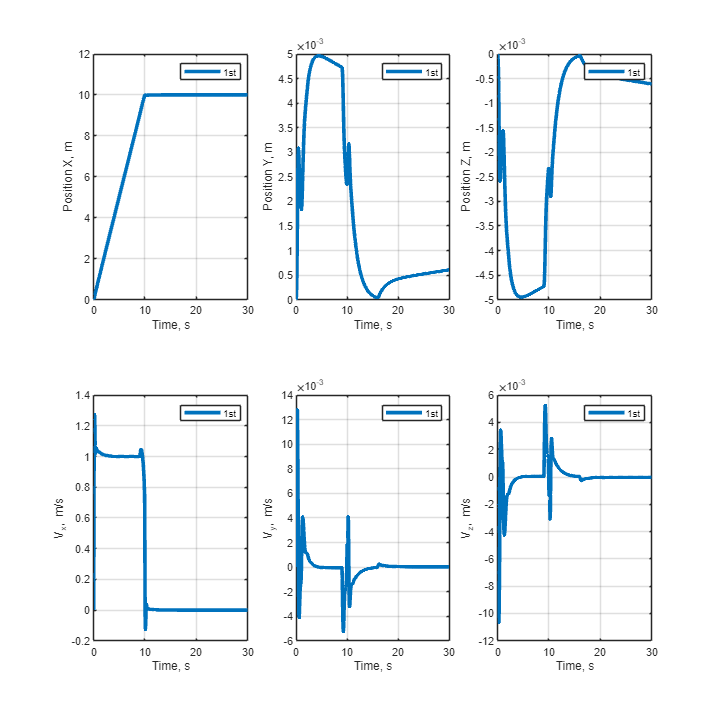

% Reference trajectory
figure('Position', [200, 200, 1200, 1200]);
set(gcf, 'Resize', 'off');

subplot(2,3,1);
plot(T, z(:,1)); grid;
xlabel('Time, s');
ylabel('Position X, m');
legend({'1st'});

subplot(2,3,2);
plot(T, z(:,2)); grid;
xlabel('Time, s');
ylabel('Position Y, m');
% legend({'Const', 'Traj'});
legend({'1st'});

subplot(2,3,3);
plot(T, z(:,3)); grid;
xlabel('Time, s');
ylabel('Position Z, m');
% legend({'Const', 'Traj'});
legend({'1st'});

subplot(2,3,4);
plot(T, z(:,4)); grid;
xlabel('Time, s');
ylabel('V_x, m/s');
% legend({'Const', 'Traj'});
legend({'1st'});

subplot(2,3,5);
plot(T, z(:,5)); grid;
xlabel('Time, s');
ylabel('V_y, m/s');
% legend({'Const', 'Traj'});
legend({'1st'});

subplot(2,3,6);
plot(T, z(:,6)); grid;
xlabel('Time, s');
ylabel('V_z, m/s');
% legend({'Const', 'Traj'});
legend({'1st'});

set(findall(gcf,'type','line'),'linewidth', 3);

### Rotational

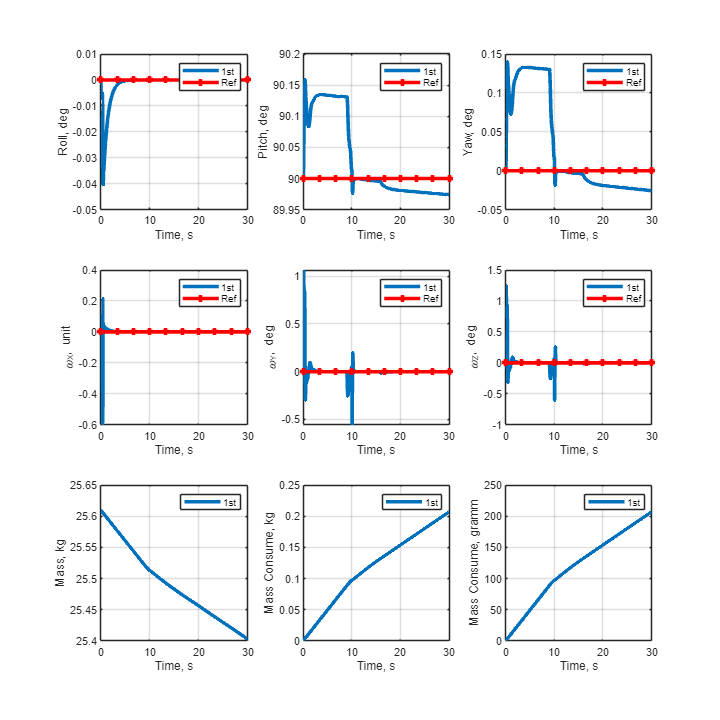

tspan = linspace(T(1), T(end), 10); 
mones = ones(1,10);
figure('Position', [200, 200, 1200, 1200]);
set(gcf, 'Resize', 'off');

subplot(3,3,1);
plot(T, rad2deg(z(:, 7)), tspan, mones* rad2deg(ref_eul(7)), 'r+-'); grid;
xlabel('Time, s');
ylabel('Roll, deg');
legend({'1st', 'Ref'});

subplot(3,3,2);
plot(T, rad2deg(z(:,8)), tspan, mones* rad2deg(ref_eul(8)), 'r+-'); grid;
xlabel('Time, s');
ylabel('Pitch, deg');
% legend({'Const', 'Traj'});
legend({'1st', 'Ref'});

subplot(3,3,3);
plot(T, rad2deg(z(:, 9)), tspan, mones* rad2deg(ref_eul(9)), 'r+-'); grid;
xlabel('Time, s');
ylabel('Yaw, deg');
% legend({'Const', 'Traj'});
legend({'1st', 'Ref'});

subplot(3,3,4);
plot(T, rad2deg(z(:,10)), tspan, mones* rad2deg(ref_eul(10)), 'r+-'); grid;
xlabel('Time, s');
ylabel('\omega_X, unit');
% legend({'Const', 'Traj'});
legend({'1st', 'Ref'});

% Euler's Rotation
subplot(3,3,5);
plot(T, rad2deg(z(:,11)), tspan, mones*rad2deg(ref_eul(11)), 'r+-'); grid;
xlabel('Time, s');
ylabel('\omega_Y, deg');
% legend({'Const', 'Traj'});
legend({'1st', 'Ref'});

subplot(3,3,6);
plot(T, rad2deg(z(:, 12)), tspan, mones*rad2deg(ref_eul(12)), 'r+-'); grid;
xlabel('Time, s');
ylabel('\omega_Z, deg');
% legend({'Const', 'Traj'});
legend({'1st', 'Ref'});


subplot(3,3,7);
plot(T, z(:,13)); grid;
xlabel('Time, s');
ylabel('Mass, kg');
% legend({'Const', 'Traj'});
legend({'1st'});

subplot(3,3,8);
plot(T, m - z(:, 13)); grid;
xlabel('Time, s');
ylabel('Mass Consume, kg');
% legend({'Const', 'Traj'});
legend({'1st'});

subplot(3,3,9);
plot(T, 1e3 * (m - z(:, 13))); grid;
xlabel('Time, s');
ylabel('Mass Consume, gramm');
% legend({'Const', 'Traj'});
legend({'1st'});

set(findall(gcf,'type','line'),'linewidth', 3);

### Forces

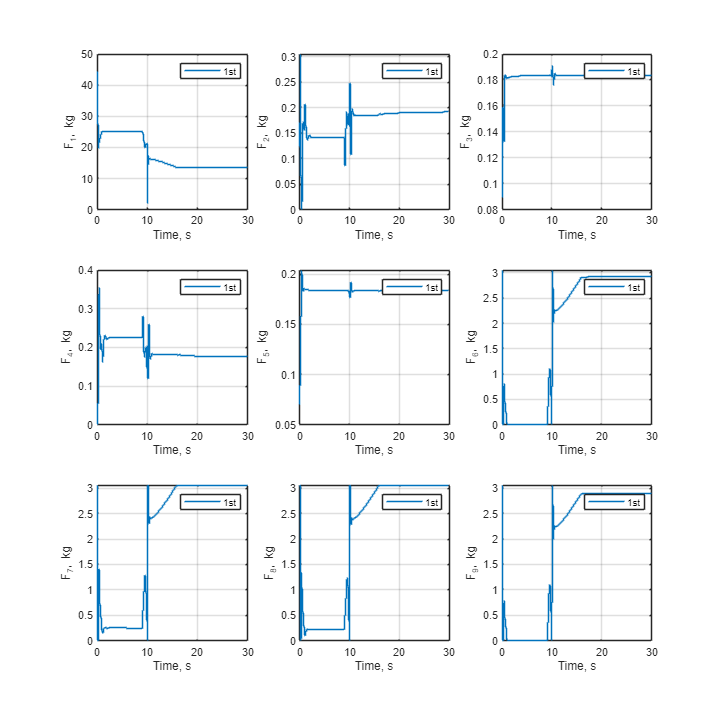

figure('Position', [200, 200, 1200, 1200]);
set(gcf, 'Resize', 'off');
Tu = T(1:end-1);
subplot(3,3,1);
stairs(Tu, Fc(1,:)); grid;
xlabel('Time, s');
ylabel('F_1, kg');
legend({'1st'});

subplot(3,3,2);
stairs(Tu, Fc(2,:)); grid;
xlabel('Time, s');
ylabel('F_2, kg');
legend({'1st'});

subplot(3,3,3);
stairs(Tu, Fc(3,:)); grid;
xlabel('Time, s');
ylabel('F_3, kg');
legend({'1st'});

subplot(3,3,4);
stairs(Tu, Fc(4,:)); grid;
xlabel('Time, s');
ylabel('F_4, kg');
legend({'1st'});

subplot(3,3,5);
stairs(Tu, Fc(5,:)); grid;
xlabel('Time, s');
ylabel('F_5, kg');
legend({'1st'});

subplot(3,3,6);
stairs(Tu, Fc(6,:)); grid;
xlabel('Time, s');
ylabel('F_6, kg');
legend({'1st'});

subplot(3,3,7);
stairs(Tu, Fc(7,:)); grid;
xlabel('Time, s');
ylabel('F_7, kg');
legend({'1st'});

subplot(3,3,8);
stairs(Tu, Fc(8,:)); grid;
xlabel('Time, s');
ylabel('F_8, kg');
legend({'1st'});

subplot(3,3,9);
stairs(Tu, Fc(9,:)); grid;
xlabel('Time, s');
ylabel('F_9, kg');
legend({'1st'});

set(findall(gcf,'type','line'),'linewidth', 3);

### Force projection

Forces = params.Hf * Fc;
Moments = params.Hm * Fc;

### Plot Force's Projections

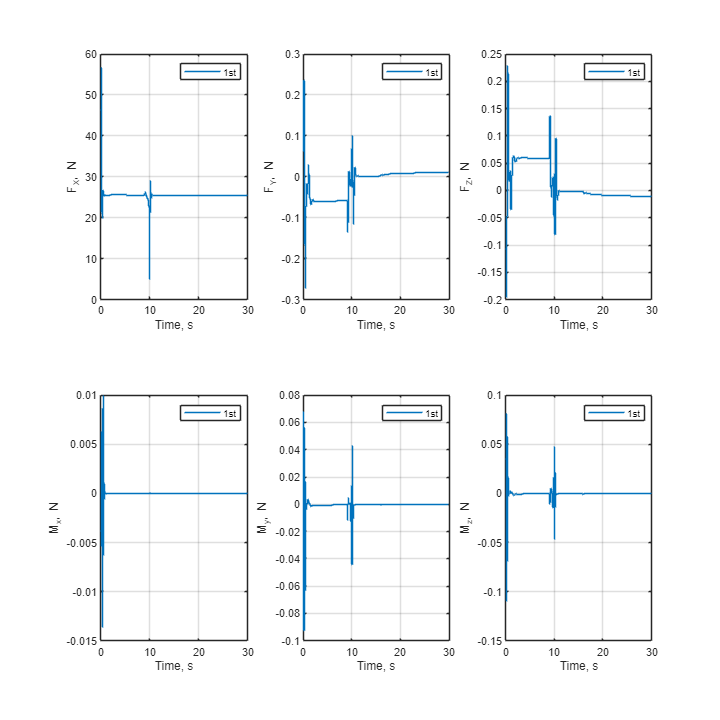

figure('Position', [200, 200, 1200, 1200]);
set(gcf, 'Resize', 'off');

subplot(2,3,1);
stairs(Tu, Forces(1,:)); grid;
xlabel('Time, s');
ylabel('F_X, N');
legend({'1st'});

subplot(2,3,2);
stairs(Tu, Forces(2,:)); grid;
xlabel('Time, s');
ylabel('F_Y, N');
legend({'1st'});

subplot(2,3,3);
stairs(Tu, Forces(3,:)); grid;
xlabel('Time, s');
ylabel('F_Z, N');
legend({'1st'});


subplot(2,3,4);
stairs(Tu, Moments(1,:)); grid;
xlabel('Time, s');
ylabel('M_x, N');
legend({'1st'});

subplot(2,3,5);
stairs(Tu, Moments(2,:)); grid;
xlabel('Time, s');
ylabel('M_y, N');
legend({'1st'});

subplot(2,3,6);
stairs(Tu, Moments(3,:)); grid;
xlabel('Time, s');
ylabel('M_z, N');
legend({'1st'});

set(findall(gcf,'type','line'),'linewidth', 3);

if SimulinkOpen
%     open("Control\6DoF_v3_quat\LQR_6DoF_v4.slx");
    open("LQR_6DoF_v4.slx");
end

## Wrap and aid functions

function ref = traj(t, t_stop, x_ref)
    vxd = x_ref(4);
    pitch_d = x_ref(8);
    if t < t_stop
        ref = [vxd*t; 0;  0;
               vxd;   0;  0;
               0;  pitch_d; 0;
               0;     0;  0];
    else
        ref = [vxd*t_stop; 0;  0;
               0;   0;  0;
               0;  pitch_d; 0;
               0;     0;  0];
    end
end


function ref = ref_traj_generator(t_now, Ts, horizon, t_stop, x_ref)
    ref = zeros(horizon, 12);  % Assuming 12 state outputs
    for i = 1:horizon
        t_next = t_now + (i-1)*Ts;
        ref(i, :) = traj(t_next, t_stop, x_ref)';  % Some function of time
    end
end


function xdot = NL_HopperDyn_ODE(t, x, u, param)
    % Dynamic Integration Step
    xdot = NL_HopperDyn(x, u, param);               % Call dynamics function
end


function xdot = NL_HopperDyn(x, u, param)
    % NL_HOPPERDYN_1 Summary of this function goes here
    %   Detailed explanation goes here
    % x(13) - State Vector 6DoF: px,py,pz, vx,vy,vz, roll,pitch,yaw,
    % wx,wy,wz, m
    % u(9)  - Control Vector: Fx,Fy,Fz, Mx,My,Mz
    % params - System Parameters: Jxx,Jyy,Jzz,Jxy,Jyz,Jxz,m,Cx,Cy,Cz,Cr,Cq,Cp,g,
    %       - beta, gamma, rho, h, d, k_quat

    %% State vector
    % r = x(1:3);           % position
    v = x(4:6);             % velocity
    a = x(7:9);             % Euler's angles
    w = x(10:12);           % angular velocity
    m = x(13);              % current mass
    
    %% Disturbances
    Fd = param.d(1:3);            % Disturbance Forces
    Md = param.d(4:6);            % Disturbance Moments
    %% Mass and Inertia matrices
    
    mdot = -u(1) * param.beta;
    rcg = mass_center_interpolate(x(13), param.mass, param.rcgs);
    [Hf, Hm] = ComponentForForces(param.geom, rcg);
    %% Control Forces
    uuu = [Hf; Hm] * u; 
    F = uuu(1:3);                       % Forces
    M = uuu(4:6);                       % Moments

    Jo = tensor_interpolation(m, param.mass, param.Inertia);
    Jdot = param.Jdot_mlt * mdot;                                            % debug
    
    Mass = diag([m, m, m]);
    %% Damping matrices
    Cv = param.Cv;
    Cw = param.Cw;
    %% DCM
    DCM = Nw(a);                                    % inertial to body DCM
    %% Gravity
    G = param.gc * DCM * [0; -param.g; 0];          % Get gravity in body frame    
    %% System of Equations 
    xdot = zeros(size(x,1), 1);                     % initialize
    xdot(1:3, 1)    = v;
    xdot(4:6, 1)    = -cross(w, v) + Mass \ (-Cv * v + F + Fd) + G;
    xdot(7:9, 1)    = Tw(a) * w;
    xdot(10:12, 1)  = Jo \ (-cross(w, Jo*w)  - Cw*w - Jdot * w + M + Md);
    xdot(13, 1)     = mdot;
end

function xdot = NL_HopperDyn_mpc_ODE(x, u, param)
    %% State vector
    % r = x(1:3);           % position
    v = x(4:6);             % velocity
    a = x(7:9);             % Euler's angles
    w = x(10:12);           % angular velocity
    %     m = x(13);              % current mass
    
    %% Disturbances
    Fd = param.d(1:3);            % Disturbance Forces
    Md = param.d(4:6);            % Disturbance Moments
    %% Mass and Inertia matrices
    
    %     mdot = -u(1) * param.beta;
    %% Control Forces
    uuu = [param.Hf; param.Hm] * u; 
    F = uuu(1:3);                       % Forces
    M = uuu(4:6);                       % Moments

    Jo = param.Jo;
    Jdot = param.Jdot;
    
    Mass = diag([param.m, param.m, param.m]);
    %% Damping matrices
    Cv = param.Cv;
    Cw = param.Cw;
    %% DCM
    DCM = Nw(a);                                    % inertial to body DCM
    %% Gravity
    G = param.gc * DCM * [0; -param.g; 0];          % Get gravity in body frame    
    %% System of Equations 
    xdot = zeros(size(x,1), 1);                     % initialize
    xdot(1:3, 1)    = v;
    xdot(4:6, 1)    = -cross(w, v) + Mass \ (-Cv * v + F + Fd) + G;
    xdot(7:9, 1)    = Tw(a) * w;
    xdot(10:12, 1)  = Jo \ (-cross(w, Jo*w)  - Cw*w - Jdot * w + M + Md);
    %     xdot(13, 1)     = param.mdot;
end

function newparams = UpdateModelParameters(params, u, dtau)
    % Copy
    newparams = params;
    % Update
    mdot = -u(1) * params.beta;
    newparams.m = params.m + mdot * dtau;
    rcg = mass_center_interpolate(newparams.m, newparams.mass, newparams.rcgs);
    [newparams.Hf, newparams.Hm] = ComponentForForces(newparams.geom, rcg);
    newparams.Jo = tensor_interpolation(newparams.m, newparams.mass, newparams.Inertia);
    newparams.Jdot = newparams.Jdot_mlt * mdot; 
end

function e = state_error_euler(x, xref)
    e = x - xref;

    % Wrap Euler angle errors to [-pi, pi]
    for ii = 7:9
        e(ii) = wrapToPi(e(ii));
    end
end